## **1. Denoising and Filtering**

(a) The input files are given as “speech.wav” and “noise.wav”. You should use function **audioread **to read the time-domain signal and the sampling frequency Fs. 

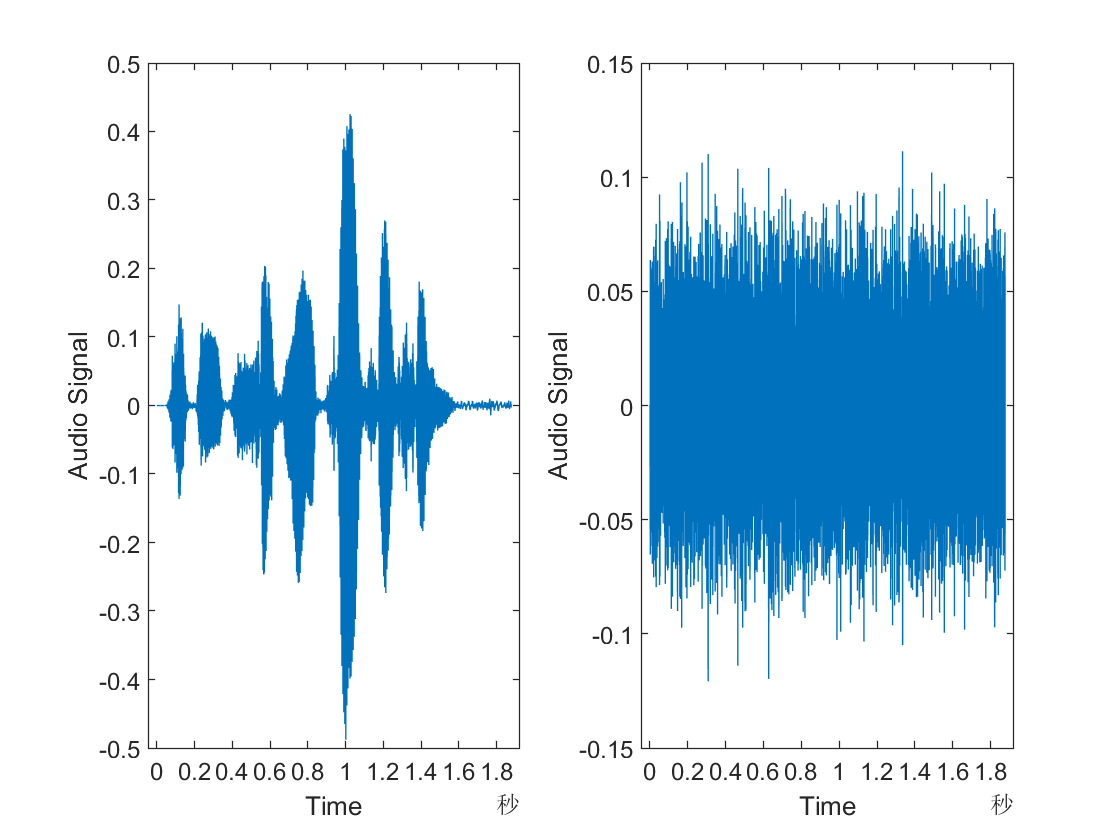

clf;
[y1,Fs1] = audioread("speech.wav");
[y2,Fs2] = audioread("noise.wav");
info1 = audioinfo("speech.wav");
info2 = audioinfo("noise.wav");
t1 = 0:seconds(1/Fs1):seconds(info1.Duration);
t1 = t1(1:end-1);
t2 = 0:seconds(1/Fs2):seconds(info2.Duration);
t2 = t2(1:end-1);
subplot(1,2,1),plot(t1,y1),xlabel("Time"),ylabel("Audio Signal")
subplot(1,2,2),plot(t2,y2),xlabel("Time"),ylabel("Audio Signal")

(b) Add noise to the speech signal. Plot the original speech signal and noised speech signal in time domain as a waveform and frequency domain as its amplitude spectrum respectively.

Hint: The x-axis of the time domain waveform should be in seconds (s), which means that you need to calculate the corresponding time of each sampling point on the timeline first. For the frequency domain, you should give the amplitude as the y-axis and concrete frequency (Hz) from 0 to Fs/2 as the x-axis. You can use function fft() and abs() to get the N-point DFT of the signal.

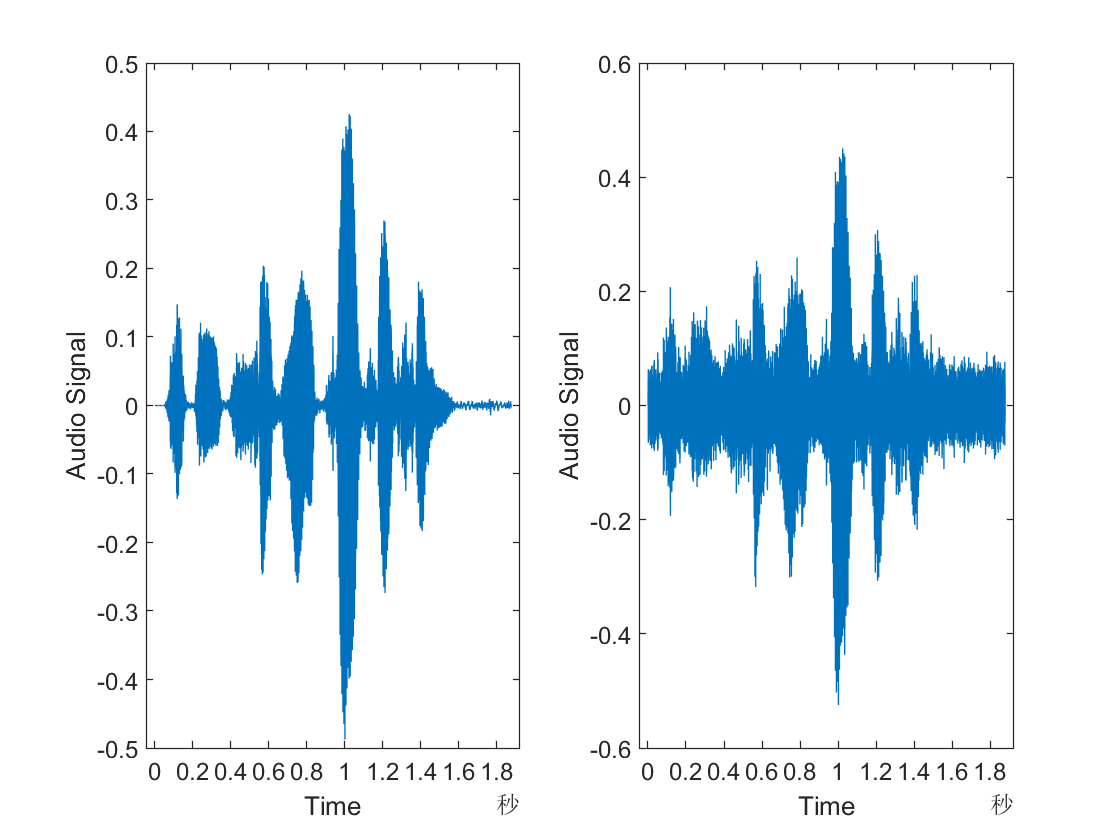

clf;
y2 = y1+y2;
subplot(1,2,1),plot(t1,y1),xlabel("Time"),ylabel("Audio Signal")
subplot(1,2,2),plot(t2,y2),xlabel("Time"),ylabel("Audio Signal")

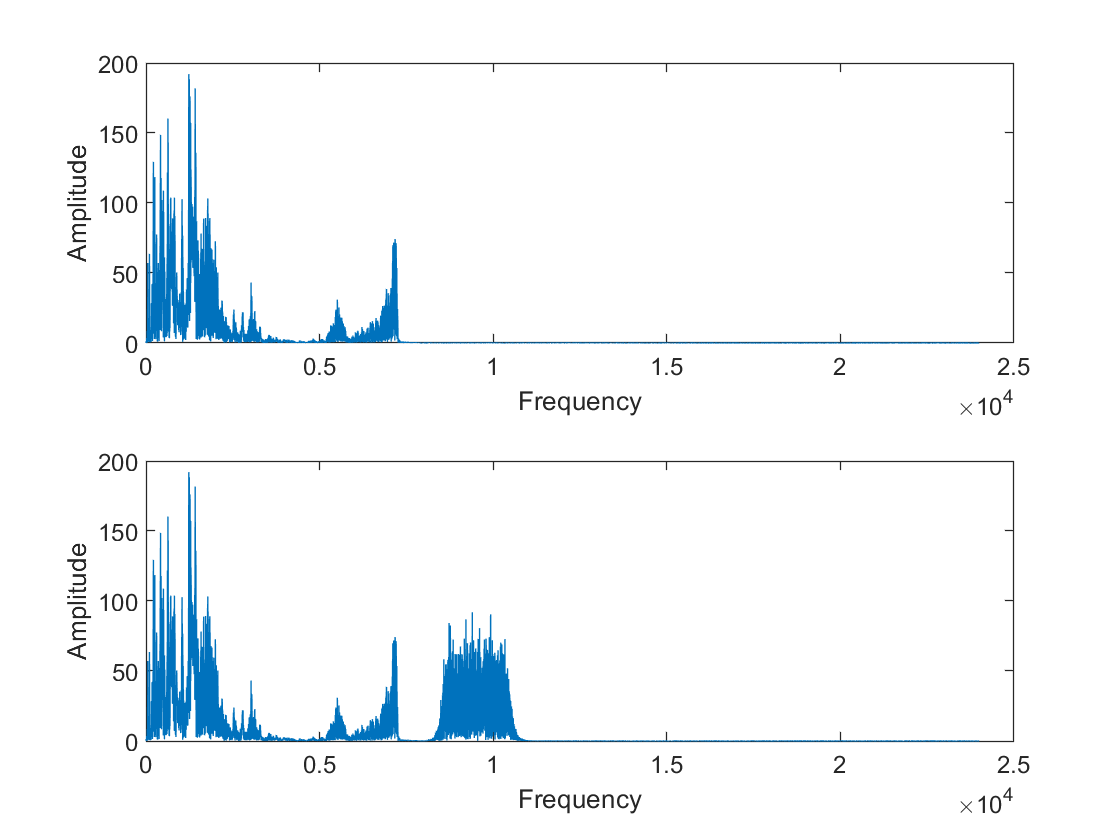

a1 = fft(y1);
a2 = fft(y2);
N1 = length(y1);
N2 = length(y2);
f1 = Fs1/N1*(0:round(N1/2)-1);
f2 = Fs2/N2*(0:round(N2/2)-1);
subplot(2,1,1),plot(f1,abs(a1(1:round(N1/2))));xlabel("Frequency"),ylabel("Amplitude")
subplot(2,1,2),plot(f2,abs(a2(1:round(N2/2))));xlabel("Frequency"),ylabel("Amplitude")

(c) The sound will be reflected back when it encounters an object in the transmission, and the auditory effect is like the echo of your shout in the valley. It is not difficult to understand that it is caused by the mixture of the original signal and the reflected signal. Therefore, the model of echo mixing can be expressed as follows:


$$y\left(t\right)=x\left(t\right)+\alpha *x\left(t-T_0 \right)$$



$$y\left(n\right)=x\left(n\right)+\alpha *x\left(n-N_0 \right)$$
                                  

Try to add echo to the noised speech signal from b). The echo is added after 1s, and the attenuation coefficient of the echo is 0.2 ($T_0 =1,\;\alpha =0\ldotp 2,\;N_0 =T_0 *F_s$). Plot the noised speech signal with echo in time domain as a waveform and frequency domain as its amplitude spectrum respectively.

Hint: You can add zeros before the start of the signal to get the echo. At the same time, the length of the signal will change by adding echo.

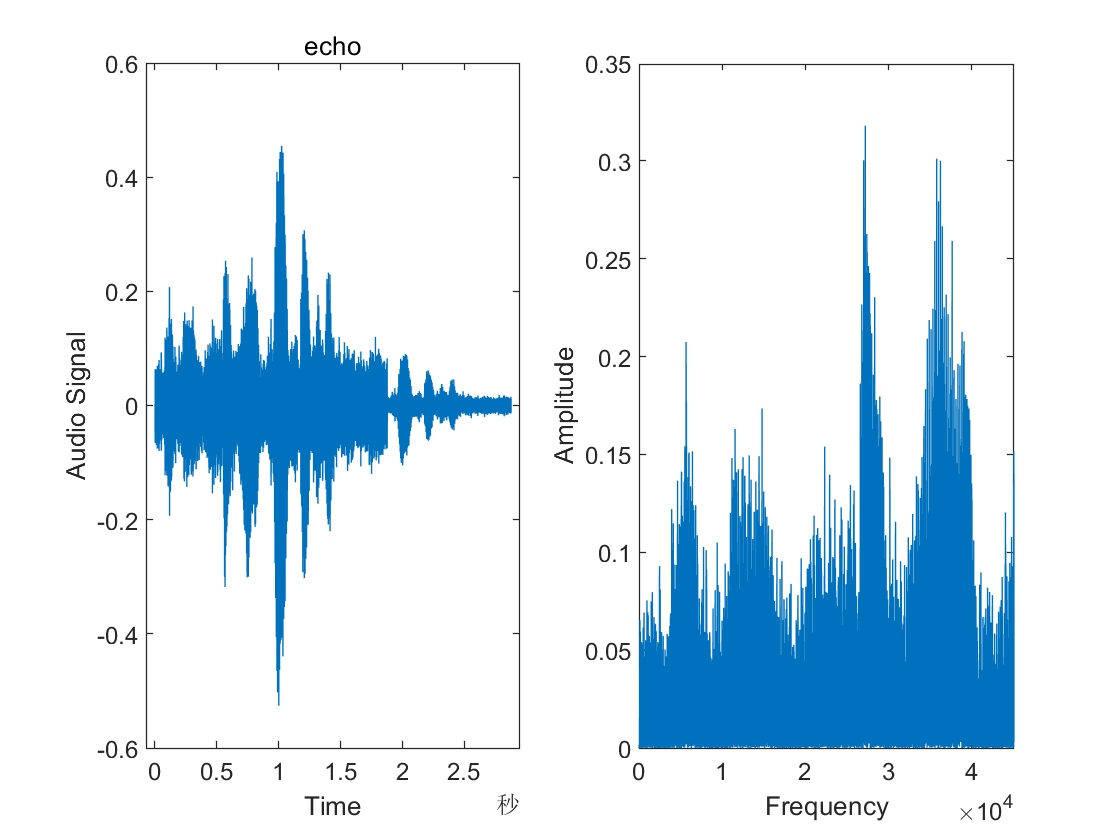

info1.Duration1 = info1.Duration +1;
N = length(y2);
x1 = y2(1:N);
x2 = y2(1:N);
x1 = [x1;zeros(48000,1)];
x2 = [zeros(48000,1);0.2*x2];
y = x1 + x2;
t = 0:seconds(1/Fs1):seconds(info1.Duration1);
t = t(1:end-1);
subplot(1,2,1),plot(t,y),xlabel("Time"),ylabel("Audio Signal"),title("echo")
a = fft(y);
subplot(1,2,2),plot(abs(y(1:round(N/2))));xlabel("Frequency"),ylabel("Amplitude")

(d) Remove the echo by inverse filtering. The Z-transform converts a discrete-time signal into a complex frequency-domain. 


$$y\left(n\right)=x\left(n\right)+\alpha *x\left(n-N_0 \right)$$



$$y\left(n\right)\iff Y\left(z\right)\;\;\;\;$$

$$x\left(n\right)\iff X\left(z\right)$$



$$Y\left(z\right)=\left(1+\alpha *z^{-N_0 } \right)X\left(z\right)=H\left(z\right)X\left(z\right)$$



$$\;\;\;\;H\left(z\right)=1+\alpha *z^{-N_0 }$$


Therefore, echo mixing can be regarded as the generation of signal  after passing through $H\left(z\right)$. Then removing the echo can be realized by inverse filtering, and the inverse system of $H\left(z\right)$ is


$$H^{-1} \left(z\right)=\frac{1}{1+\alpha *z^{-N_0 } }$$


You can use function **filter **to implement inverse filtering as follow:

$b=\left\lbrack 1\right\rbrack ;a=\left\lbrack 1,\textrm{zeros}\left(1,N_0 -1\right),\alpha \right\rbrack$;


$$x=\textrm{filter}\left(b,a,y\right);$$


Try to implement inverse filtering to the noised speech signal with echo from c) to remove the echo. Plot the signal before and after the inverse filtering in time domain as a waveform respectively. 

Hint: You can use function** sound** to play the speech signal to verify whether the elimination of echo is successful

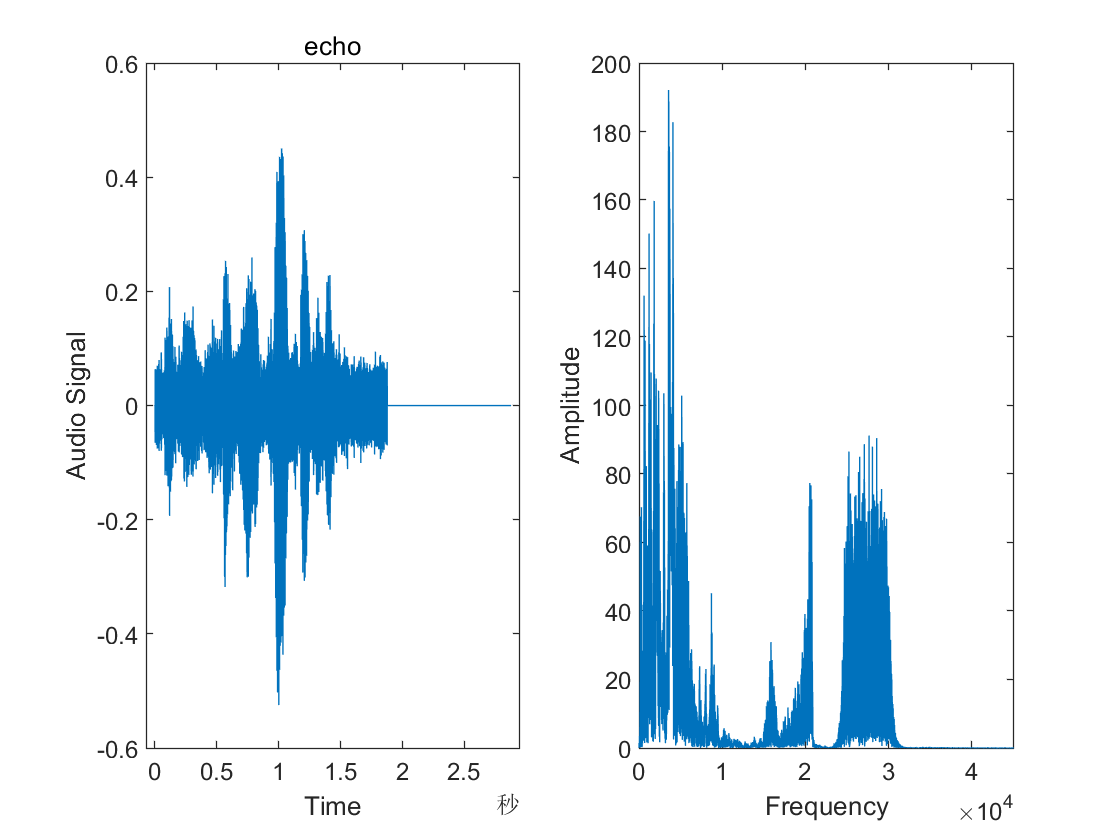

clf;
b = [1];
a = [1,zeros(1,48000-1),0.2];
x = filter(b,a,y);
subplot(1,2,1),plot(t,x),xlabel("Time"),ylabel("Audio Signal"),title("echo")
am = fft(x);
subplot(1,2,2),plot(abs(am(1:round(N1/2))));xlabel("Frequency"),ylabel("Amplitude")

(e) Design a FIR filter use **fdatool** command and filter the noised speech signal without echo from d) with function filter to remove the noise. You are required to declare the filter type you used and briefly explain the design parameters you choose. You are then required to plot: (1) The magnitude response of the filter in frequency domain; (2) The noised speech signal without echo from d) and the filtered signal in time domain as a waveform and frequency domain as its amplitude spectrum respectively.

Hint: You can also use function **sound** to play the speech signal to verify whether the elimination of noise is successful

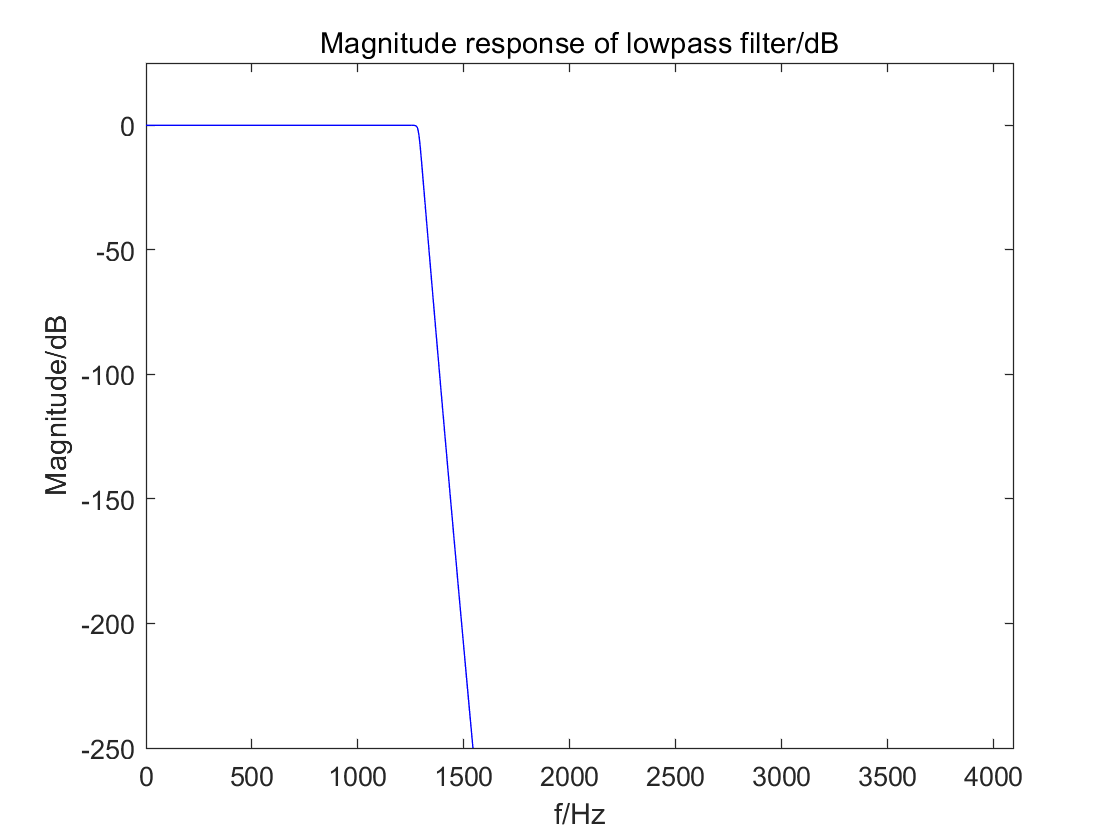

% declare the filter type you used and briefly explain the design parameters you choose 
%
Hd = lowpass_filter;
[H,w] = freqz(Hd);
dbH=20*log10(abs(H)/max(abs(H)));
figure
plot(w*Fs/(2*pi), dbH,'b'); 
axis([0 Fs/2 -250 25]);
title('Magnitude response of lowpass filter/dB');
xlabel('f/Hz');ylabel('Magnitude/dB');

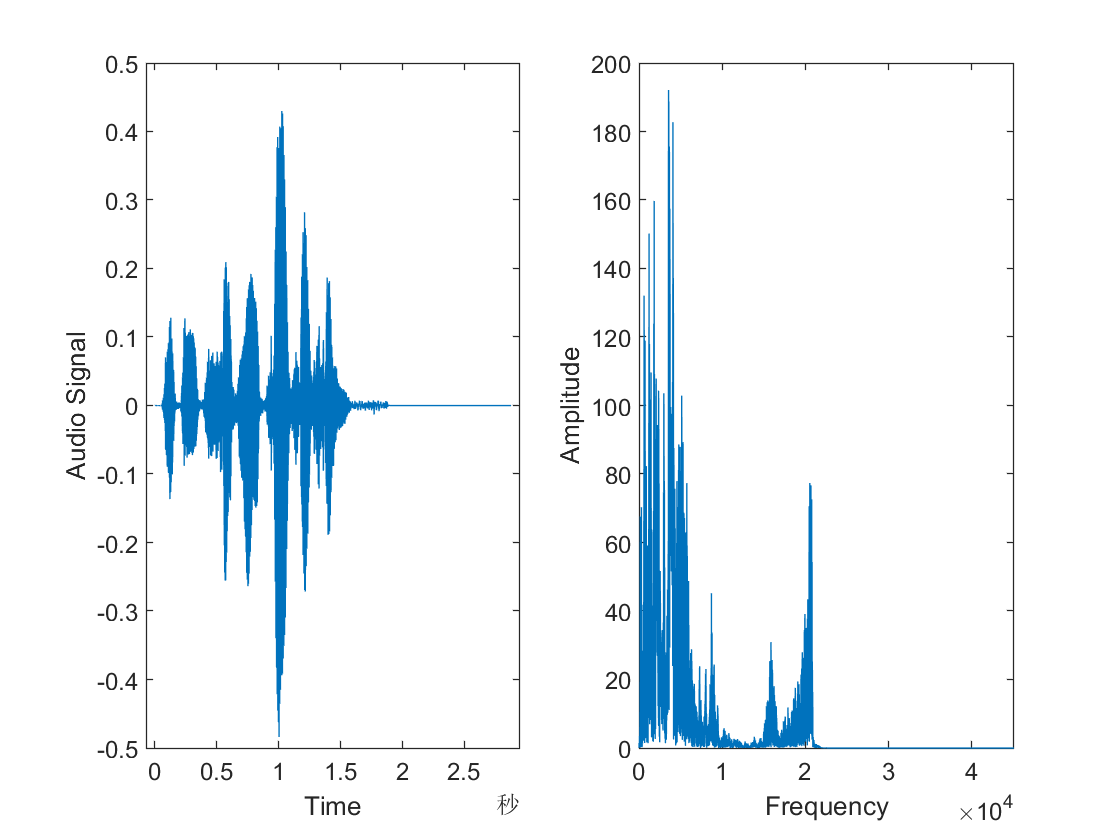

%explanation:because the frequency of the noise is on the high level
%so i design a lowpass_filter to filter the high level frequency
%to save the low frequency of the speech signal
x = filter(b,a,y);
y=filter(Hd,x);
t = 0:seconds(1/Fs1):seconds(info1.Duration1);
t = t(1:end-1);
subplot(1,2,1),plot(t,y),xlabel("Time"),ylabel("Audio Signal")
am = fft(y);
subplot(1,2,2),plot(abs(am(1:round(N1/2))));xlabel("Frequency"),ylabel("Amplitude")

## 2. **Audio Signal Processing **

(a)The input file is given as “handel.wav”. You should use function **audioread **to read the time-domain signal and the sampling frequency Fs. 

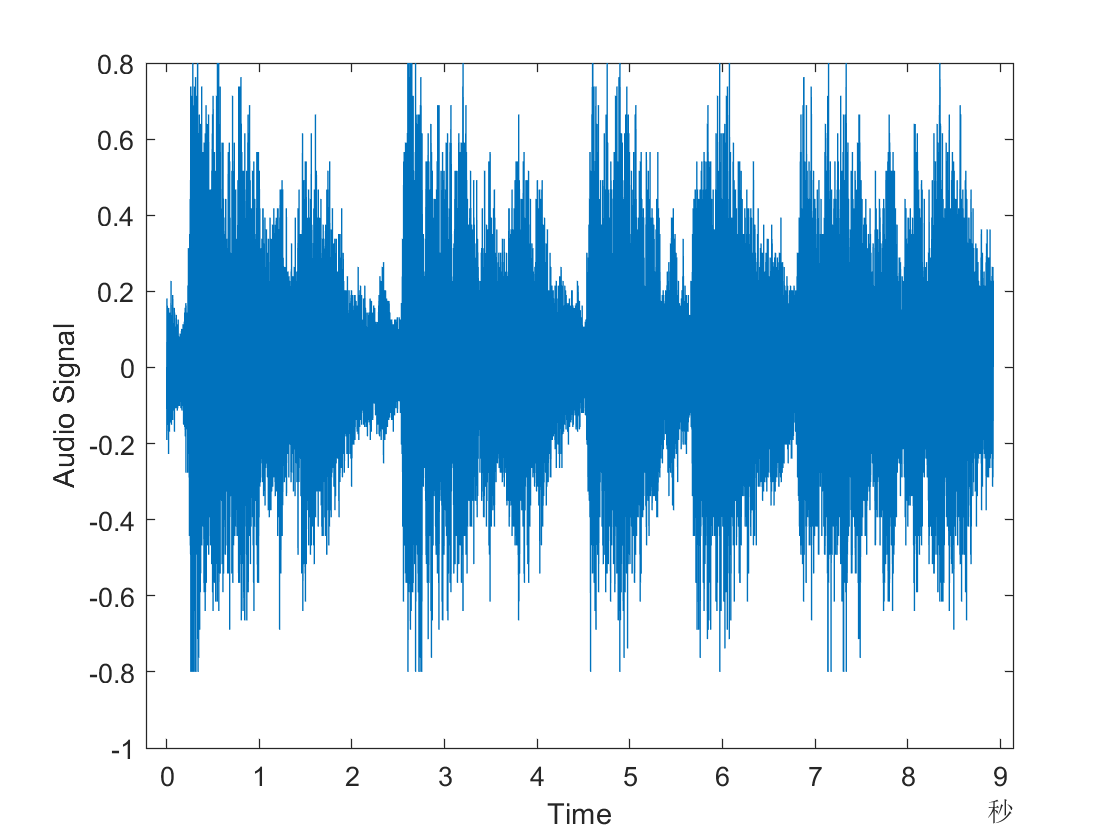

clf;
[y,Fs] = audioread("handel.wav");
info = audioinfo("handel.wav");
t = 0:seconds(1/Fs):seconds(info.Duration);
t = t(1:end-1);
plot(t,y),xlabel("Time"),ylabel("Audio Signal")

(b)Plot the signal in time domain as a waveform and frequency domain as its amplitude spectrum. The x-axis of the time domain waveform should be in seconds (s). For the frequency domain, you should give the amplitude as the y-axis and concrete frequency (Hz) from 0 to Fs/2 as the x-axis. You can first use function **fft() **and** abs()** to get the N-point DFT of the signal.

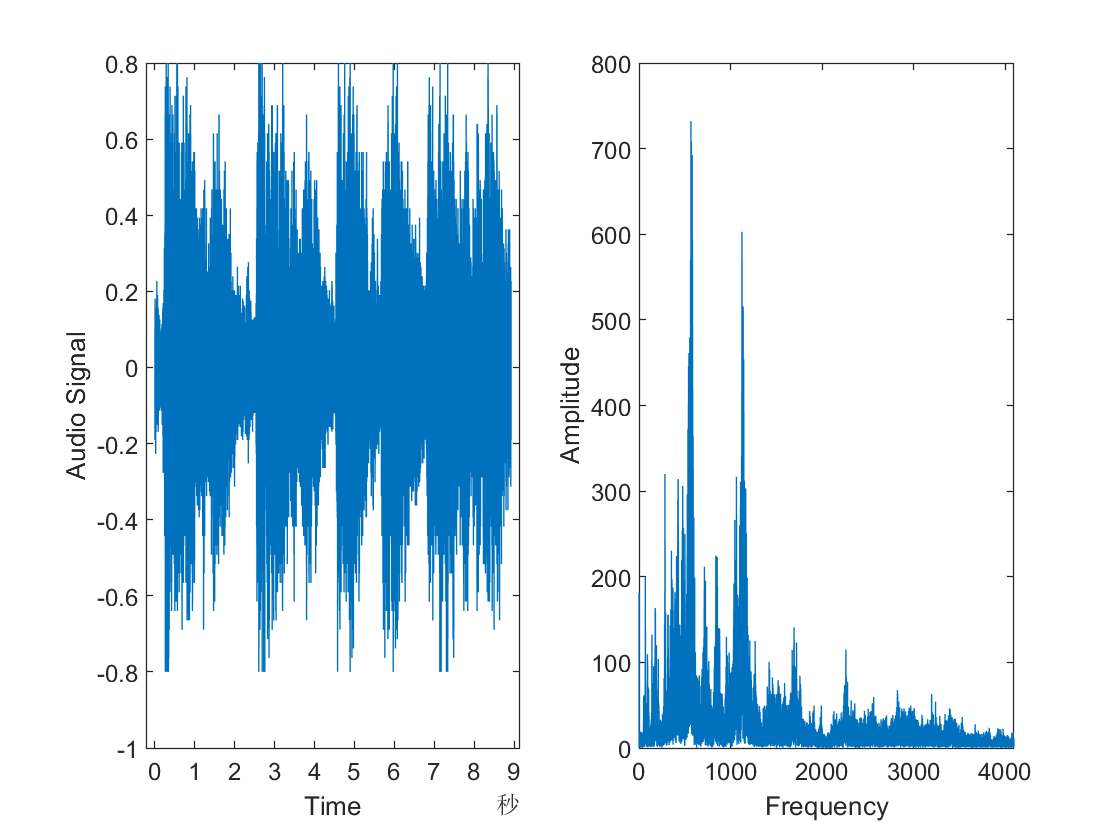

clf;
subplot(1,2,1),plot(t,y),xlabel("Time"),ylabel("Audio Signal")
a = fft(y);
N = length(y);
f = Fs/N*(0:round(N/2)-1);
subplot(1,2,2),plot(f,abs(a(1:round(N/2))));xlabel("Frequency"),ylabel("Amplitude")

(c)Make a simple equalizer. The equalizer allocates different weights various different frequency bandwidth. This can be realized by a couple of band-pass filters. In this case, eight filters are adopted for 32, 64, 125, 250, 500, 1k, 2k and 4kHz. Design the filters as you prefer and splice the signals filtered by your filters. Before filtering, consider the following questions. What is the filter type you choose? Is it time-domain or frequency domain? Is it IIR or FIR filter? What is the reason that you choose it? After that, Plot the spectrum of the difference of the original signal and filtered signal. (The difference should be minimized as far as possible, which is your task.)

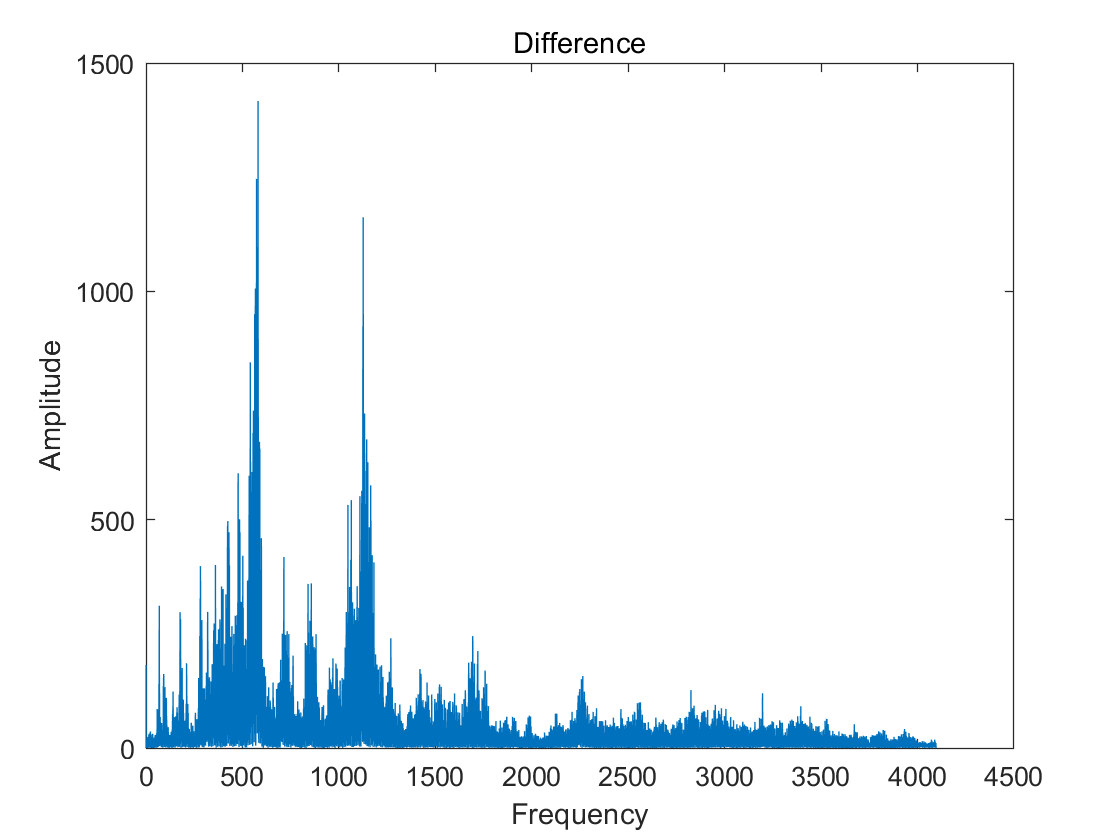

clf;
a0 = filter(passband0,y);
a1 = filter(passband1,y);
a2 = filter(passband2,y);
a3 = filter(passband3,y);
a4 = filter(passband4,y);
a5 = filter(passband5,y);
a6 = filter(passband6,y);
a7 = filter(passband7,y);
a = a0+a1+a2+a3+a4+a5+a6+a7;
y = y - a;
e = fft(y);
plot(f,abs(e(1:round(N/2))));xlabel("Frequency"),ylabel("Amplitude"),title("Difference")

(d)Assign weights for each filter to make the voice of human clearer. The values of weights can range from -12dB to 12dB. Plot the spectrum of the filtered signals again and save it through function **audiowrite**. 

Hint: dB is a parameter describing gain. $G\left(w\right)=20\log_{10} \left(\left|H\left(e^{\textrm{jw}} \right)\right|\right)$

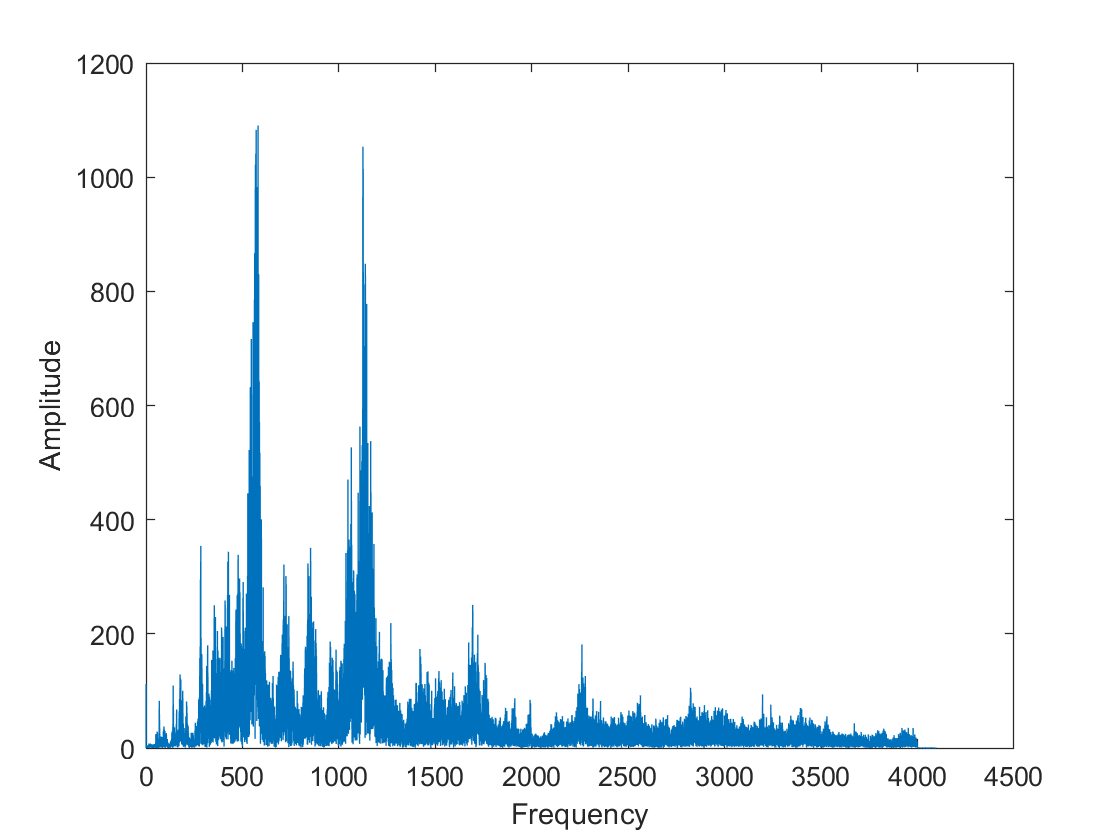

clf;
y = (a0*0.4 + a1*0.4 + a2*0.4 + a3*0.8 + a4*1.1 + a5*1.5 + a6*1.7 + a7*1.5)/100;
audiowrite("music.wav",y,Fs);
[y,Fs] = audioread("music.wav");
y = y*100;
e = fft(y);
plot(f,abs(e(1:round(N/2))));xlabel("Frequency"),ylabel("Amplitude")

(e)Implement the voice transferring (voice to the opposite gender). Use function **resample **to try it. However, there may be two problems. When we upsample the audio, we need to drop out weak signals. When we downsample the audio, we need to padding to maintain the length of the audio. Plot the time-domain sequence and Fourier spectrum before and after the voice transferring. 

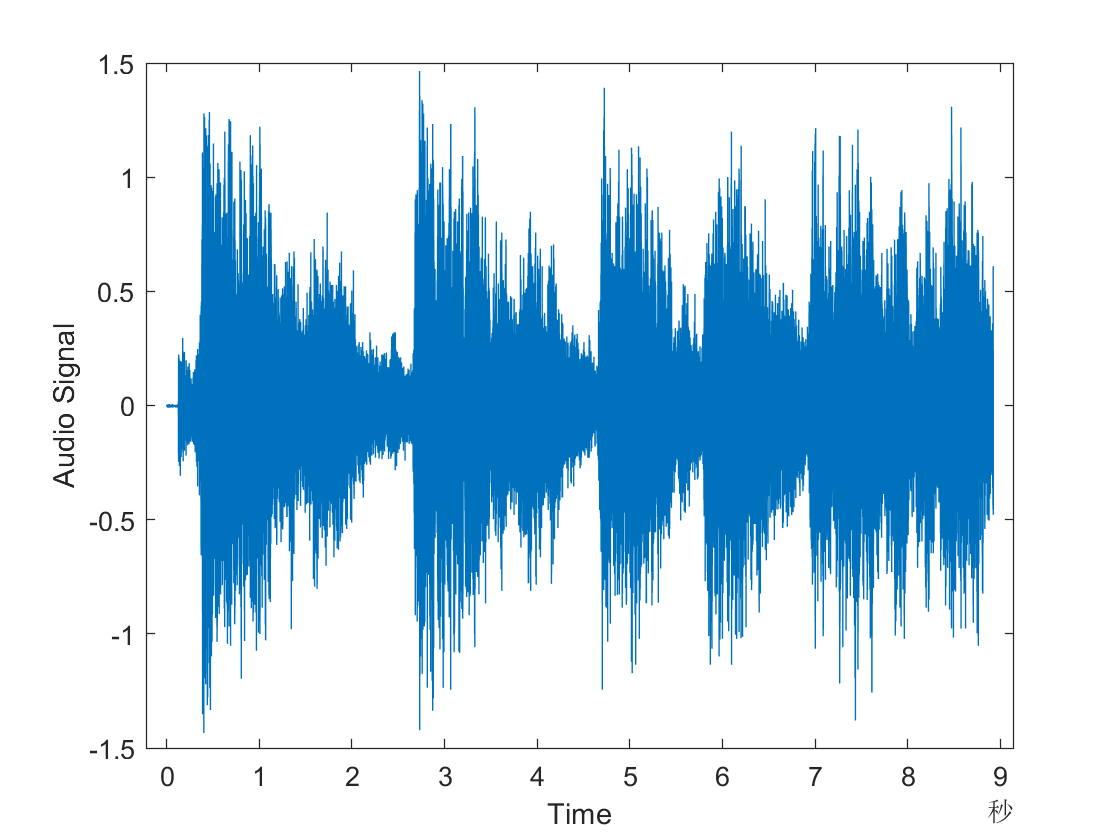

clf;
t = 0:seconds(1/(Fs)):seconds(info.Duration);
t = t(1:end-1);
plot(t,y),xlabel("Time"),ylabel("Audio Signal")

e = fft(y);
N = length(y);
f = Fs/N*(0:round(N/2)-1);
plot(f,abs(e(1:round(N/2))));xlabel("Frequency"),ylabel("Amplitude")

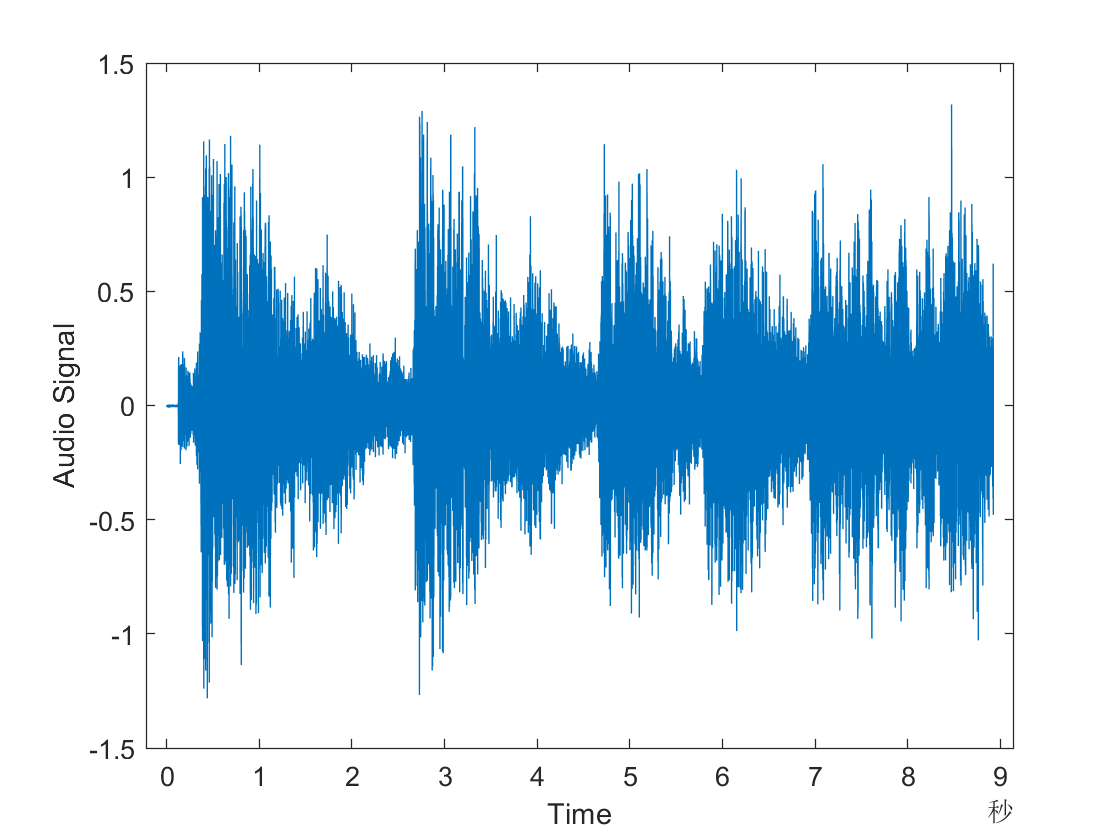

b = resample(y,1,3);
b1 = y;
for i = 1:1:24370
    num = (b(i) - b(i+1))/3;
    b1(3*i-2) = b(i);
    b1(3*i-1) = b(i)-num;
    b1(3*i) = b(i)-2*num;
end
t2 = 0:seconds(1/Fs):seconds(info.Duration);
plot(t,b1),xlabel("Time"),ylabel("Audio Signal")

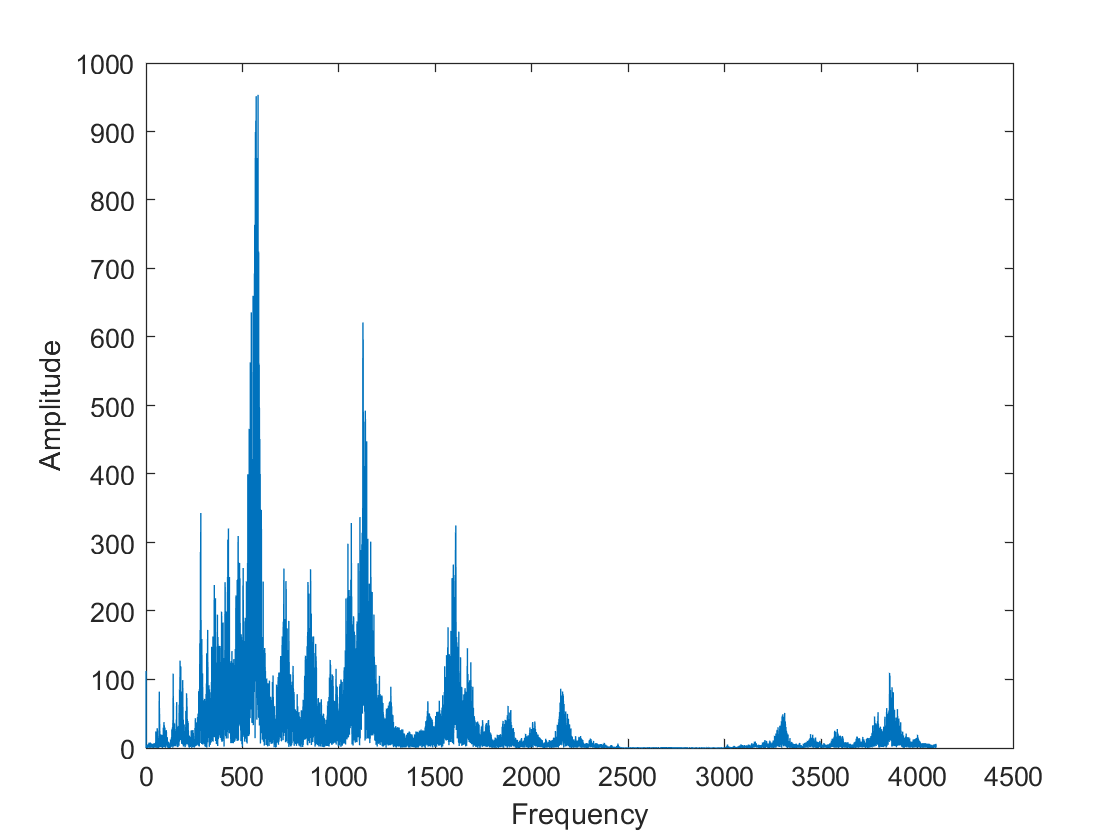

e2 = fft(b1);
N2 = length(b1);
f2 = Fs/N2*(0:round(N2/2)-1);
plot(f2,abs(e2(1:round(N2/2))));xlabel("Frequency"),ylabel("Amplitude")